# 3. 画像の線形フィルタリング

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## 平均フィルタ

画像 $\mathbf{u}$ に2次元フィルタ $\mathbf{h}$ を適用する（畳込み）ことによって、様々な処理が行える．

まずは平均フィルタを考える．フィルタの（縦・横方向の）サイズ $k$ を決め，正方形の平均値フィルタを作成する．

k = 9;
h = ones(k,k);
h = h/sum(h(:)); % 各画素を中心として 9x9 のウィンドウで平均化するフィルタ 
h

h =     0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123
    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123


作成した平均フィルタカーネルを読み込んだ画像に畳込む．

name = 'house';
u = load_image(name, []);
uh = perform_convolution(u,h);

フィルタリング前後の画像を表示（焦点ボケ）．

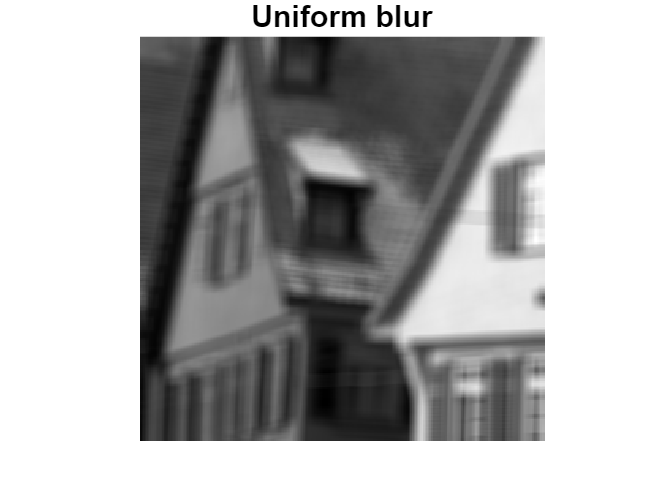

clf;
imageplot(u, 'Input');
clf;
imageplot(uh, 'Uniform blur');

特定の方向に平均化するフィルタ．

k = 15;
h = eye(k,k);
h = h/sum(h(:)); % 斜めに平均化
h

h =     0.0667         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0667         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0667         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.0667         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.0667         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.0667         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0667         0         0

uh = perform_convolution(u,h);

フィルタリング前後の画像を表示（手ブレ）．

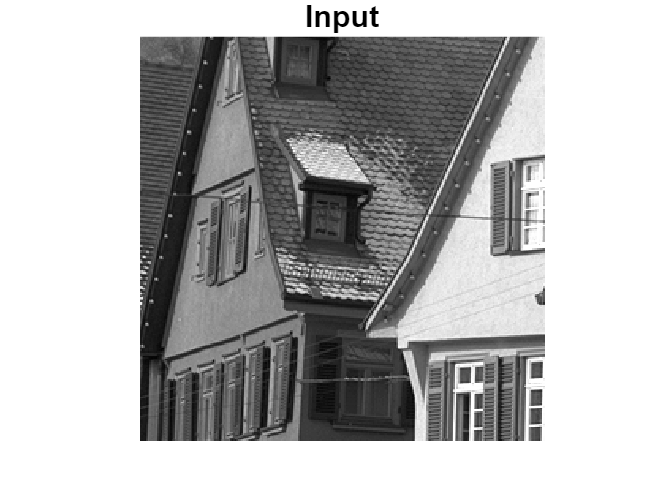

clf;
imageplot(u, 'Input');

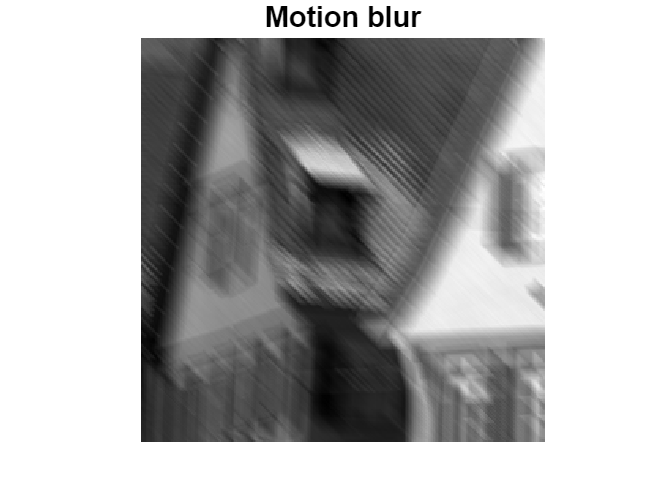

clf;
imageplot(uh, 'Motion blur');

## 差分フィルタ

横方向の一次差分フィルタ．

k = 3;
h = zeros(k,k);
h(2,1) = -1;
h(2,2) = 1;
h

h =      0     0     0
    -1     1     0
     0     0     0


uh = perform_convolution(u,h);

フィルタリング前後の画像を表示（垂直エッジ画像）．

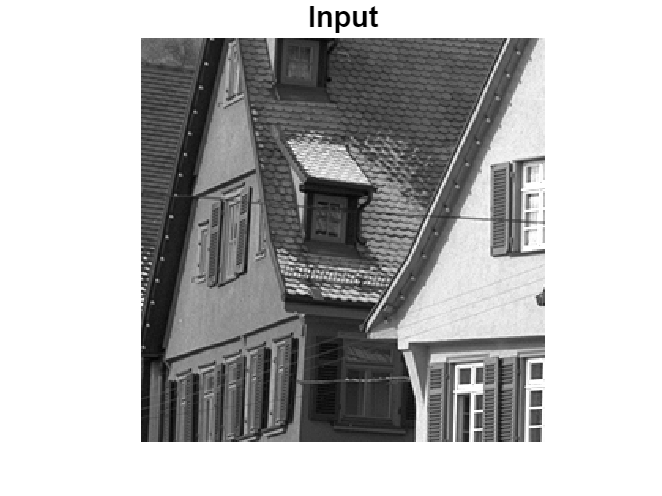

clf;
imageplot(u, 'Input');

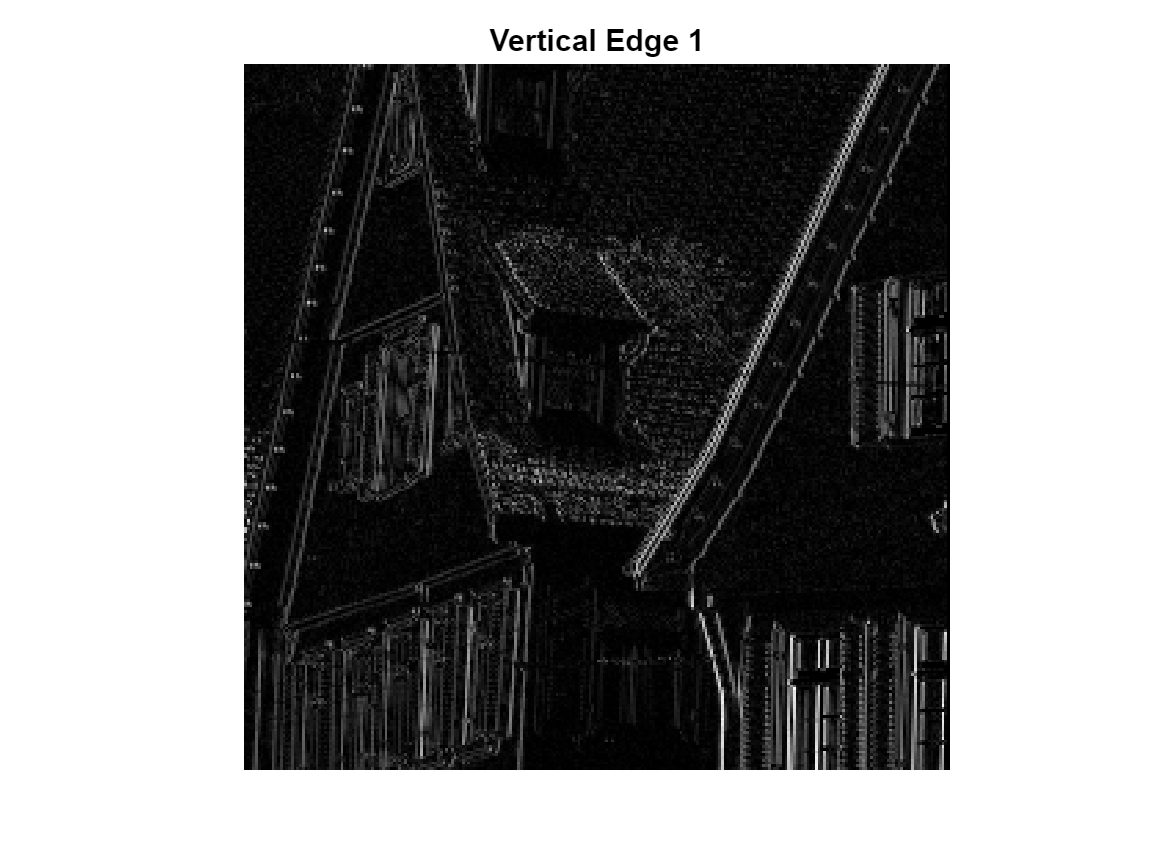

clf;
imageplot(abs(uh), 'Vertical Edge 1');

横方向の二次差分フィルタ．

k = 3;
h = zeros(k,k);
h(2,1) = -1;
h(2,2) = 2;
h(2,3) = -1;
h

h =      0     0     0
    -1     2    -1
     0     0     0


uh = perform_convolution(u,h);

フィルタリング前後の画像を表示（垂直エッジ画像）．

clf;
imageplot(u, 'Input');

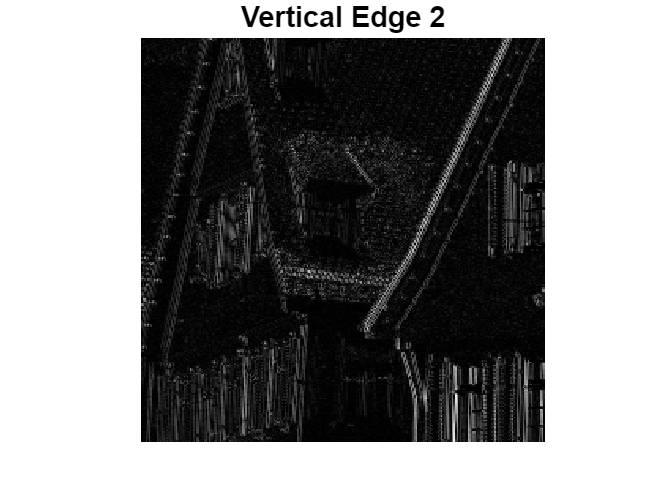

clf;
imageplot(abs(uh), 'Vertical Edge 2');

ラプラシアンフィルタ（縦横二次差分フィルタ）．

k = 3;
h = zeros(k,k);
h(1,2) = -1;
h(2,1) = -1;
h(2,3) = -1;
h(3,2) = -1;
h(2,2) = 4;
h

h =      0    -1     0
    -1     4    -1
     0    -1     0


uh = perform_convolution(u,h);

フィルタリング前後の画像を表示（エッジ画像）．

clf;
imageplot(u, 'Input');

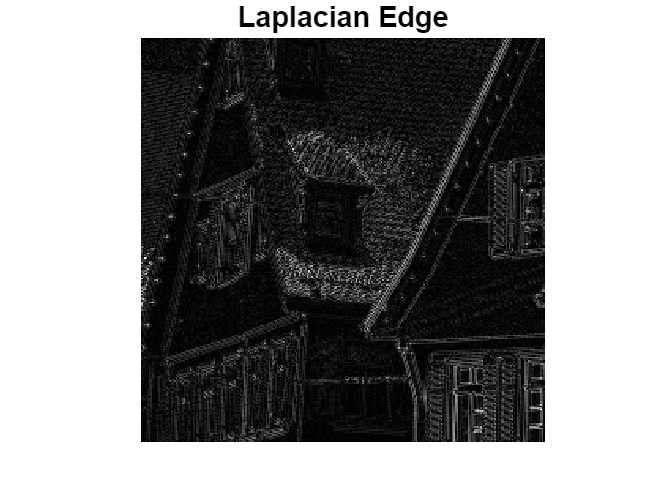

clf;
imageplot(abs(uh), 'Laplacian Edge');

## **演習問題**

**演習3-1**: グレースケール画像'house'を読み込み，斜め方向（左斜め・右斜め両方）のエッジを抽出する3x3二次差分フィルタを作成し適用した結果（処理前後両方）を表示せよ．

k = 3;
h = zeros(k,k);
h(1,2) = -1;
h(2,1) = 1;
h

h =      0    -1     0
     1     0     0
     0     0     0


uh = perform_convolution(u,h);

clf;
imageplot(u, 'Input');

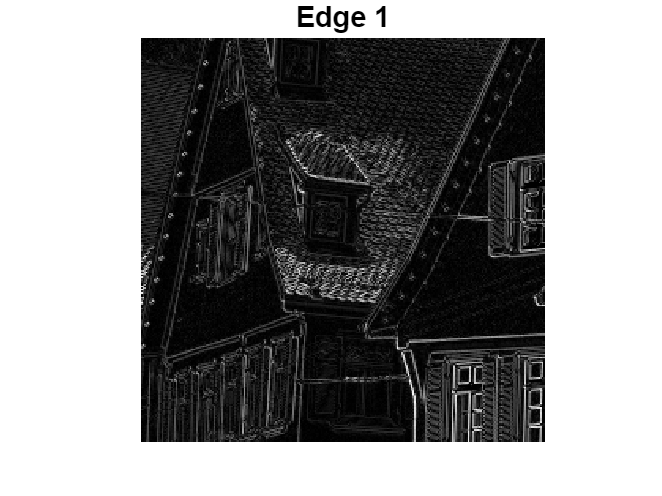

clf;
imageplot(abs(uh), 'Edge 1');


k = 3;
h = zeros(k,k);
h(1,1) = -1;
h(2,2) = 1;
h

h =     -1     0     0
     0     1     0
     0     0     0


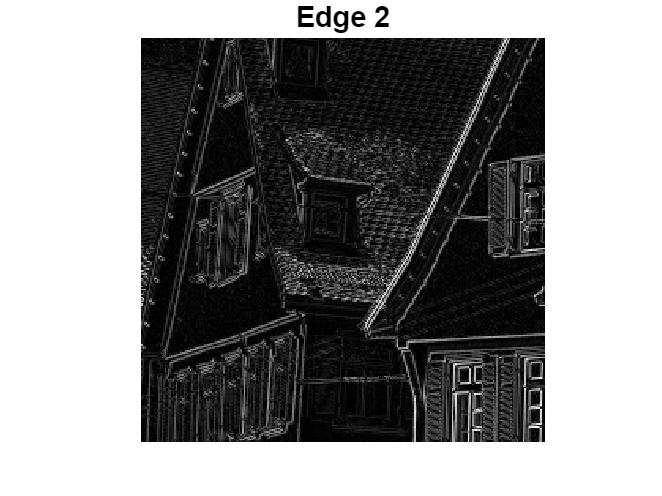

uh = perform_convolution(u,h);
clf;
imageplot(abs(uh), 'Edge 2');

**演習3-2**: グレースケール画像'house'を読み込み，ラプラシアンフィルタを利用してエッジを強調した結果（処理前後両方）を表示せよ．

ヒント：エッジ強調後の画素値はマイナスや255を超えるため，区間[0,255]に丸め込むと良い．

k = 3;
h = zeros(k,k);
h(1,1) = -1;
h(1,2) = -1;
h(1,3) = -1;
h(2,1) = -1;
h(2,3) = -1;
h(3,1) = -1;
h(3,2) = -1;
h(3,3) = -1;
h(2,2) = 8;
h

h =     -1    -1    -1
    -1     8    -1
    -1    -1    -1


uh = perform_convolution(u,h);

clf;
imageplot(u, 'Input');

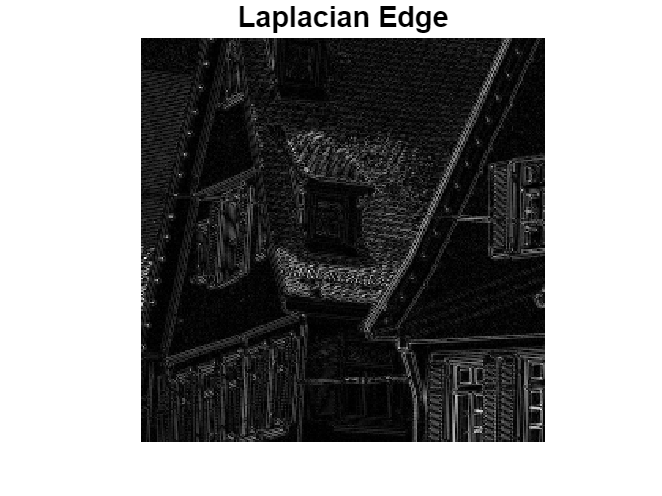

clf;
imageplot(abs(uh), 'Laplacian Edge');